## Import Data

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 10);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ";";

% Specify column names and types
opts.VariableNames = ["n", "Caste", "ID", "colony", "dissection_date", "time_inf_exp", "ant_age", "rep_cycle", "dur_cycle", "Infec_intensity"];
opts.VariableTypes = ["double", "categorical", "double", "string", "datetime", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "colony", "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Caste", "colony", "rep_cycle"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "dissection_date", "InputFormat", "dd.MM.yy");

% Import the data
casteInf = readtable("/Users/lizimai/Desktop/postTrack/InfectionDynamics/infection_dynamics.csv", opts);


## Plot Data

setColorMap;

hexMap = 1×3 cell array
    {'2596be'}    {'e28743'}    {'873e23'}


thisCell = '2596be'

r = 37

g = 150

b = 190

myColorMap =     37   150   190
     0     0     0
     0     0     0


thisCell = 'e28743'

r = 226

g = 135

b = 67

myColorMap =     37   150   190
   226   135    67
     0     0     0


thisCell = '873e23'

r = 135

g = 62

b = 35

myColorMap =     37   150   190
   226   135    67
   135    62    35


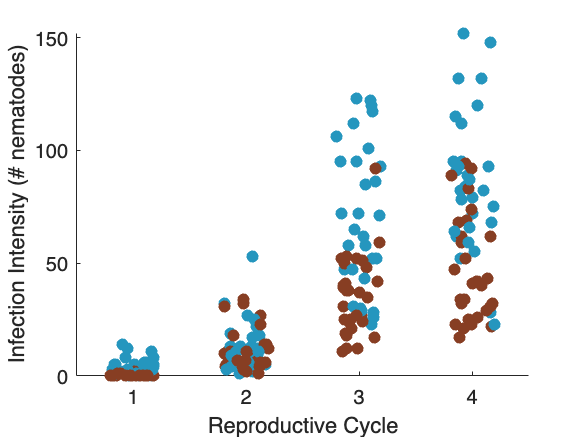

colormap(myColorMap);
scatter(casteInf, "rep_cycle", "Infec_intensity", 'filled', 'ColorVariable', "Caste", 'jitter', 'on')
xlabel("Reproductive Cycle")
ylabel("Infection Intensity (# nematodes)")

## Statistics

casteInf.Infec_intensity_trs = (casteInf.Infec_intensity).^(1/3)

casteInf = 240×11 table
    n      Caste     ID    colony    dissection_date    time_inf_exp    ant_age    rep_cycle    dur_cycle    Infec_intensity    Infec_intensity_trs
    __    _______    __    ______    _______________    ____________    _______    _________    _________    _______________    ___________________

     1    Forager     1     "n1"        23.07.18             34           108          1           35               6                 1.8171       
     2    Forager     2     "n1"        23.07.18             34           108          1           35               4                 1.5874       
     3   

glme = fitlme(casteInf, "Infec_intensity_trs ~ 1 + Caste * rep_cycle + (1|colony)")

glme = Linear mixed-effects model fit by ML

Model information:
    Number of observations             240
    Fixed effects coefficients           4
    Random effects coefficients          3
    Covariance parameters                2

Formula:
    Infec_intensity_trs ~ 1 + Caste*rep_cycle + (1 | colony)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    478.78    499.67    -233.39          466.78  

Fixed effects coefficients (95% CIs):
    Name                             Estimate     SE          tStat       DF     pValue        Lower        Upper  
    {'(Intercept)'          }          0.33583     0.19292      1.7408    236      0.083017    -0.044224    0.71589
    {'Caste_Nurse'          }          -0.6365     0.19928      -3.194    236     0.0015945      -1.0291    -0.2439
    {'rep_cycle'            }           1.0634    0.051455      20.668    236    7.2979e-55      0